# How photons become electrons and preserve the Poisson distribution

## The Poisson distribution

The Poisson distribution describes the statistics of a series of 'events'. For light an event is the arrival of a photon. 

The defining property of a Poisson distribution is that the chance of an event is the same at each small interval of time. 

Suppose that for each small unit of time, $\delta T$ the probability that a photon will arrive is constant, $\rho$. 

duration  = 0.1;             % Exposure duration
deltaT    = 1e-4;            % A millisecond
rho       = 1e-2;            % Chance of a photon in deltaT
T = deltaT:deltaT:duration;  % Time samples over 0.1 sec

## Time series

We can simulate the probably of an event happening or not, in each instance, using the binomial distribution. Here is a plot with a line at each moments when there is (1) or is not (0) a photon.

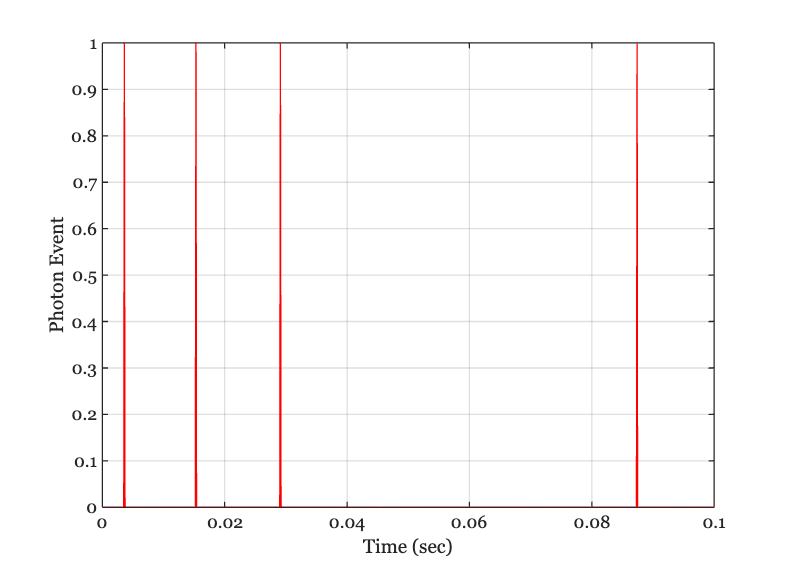

photons = binornd(1,rho,length(T),1);
iePlot(T,photons);
xlabel('Time (sec)'); ylabel('Photon Event'); grid on

fprintf('There were %d photons in this sample.\n',sum(photons));

There were 4 photons in this sample.


## Now, run many samples and make a histogram of the counts

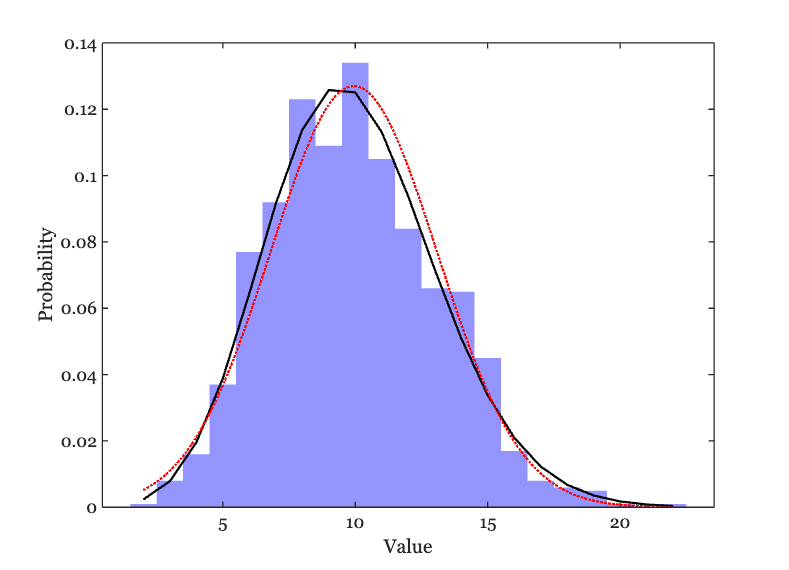

nSamples = 1000;
cnt = zeros(1,nSamples);
for ii=1:nSamples
    photons = binornd(1,rho,length(T),1);
    cnt(ii) = sum(photons);
end

mu = mean(cnt);
sigma = std(cnt);

ieFigure;

% Create the histogram
h = histogram(cnt, 'Normalization', 'probability');
h.EdgeColor = 'none';
h.FaceColor = [0.3 0.3 1];

hold on; % Prevent the next plot from overwriting the histogram

% Calculate the Probability Mass Function (PMF) of the Poisson distribution
xmin = min(cnt);
xmax = max(cnt);
x = xmin:xmax;
lambda = mu;
f = (lambda.^x .* exp(-lambda)) ./ factorial(x);   
plot(x, f, 'k-', 'LineWidth', 2); % 'r-' for a red solid line

% Calculate the probability density function (PDF) of the Normal distribution
x = linspace(min(cnt), max(cnt), 100);
f = exp(-(x - mu).^2 / (2 * sigma^2)) / (sigma * sqrt(2 * pi));
plot(x, f, 'r:', 'LineWidth', 2); % 'r-' for a red solid line

% Add labels and title
xlabel('Value');
ylabel('Probability');
% title('Histogram with Normal Distribution Overlay');
% legend('Histogram', 'Normal Distribution');

hold off; % Allow subsequent plots to overwrite this one

The mean and variance are equal in the Poisson

fprintf('Mean %.3f Variance %0.3f\n',mean(cnt),var(cnt));

Mean 9.945 Variance 9.862


## Photon to electron conversion

At the sensor, an event is when a photon creates an electron. For a CMOS or CCD image sensor, each photon turns into one electron or no electrons. 

Suppose the probability of a photon generating an electron is $\epsilon$. Let's set epsilon to one half, as an example.

epsilon = 0.3;

The probability of conversion is the same whenever the photon arrives. Here is the probability of the conversion, which is also a Poisson distribution.

eConversion = binornd(1,epsilon,length(T),1);

## Each photon may become an electron

The probability is the same in each little time interval, and thus the whole calculation is Poisson.

electrons = photons .* eConversion;

Here is a plot of the electrons. This is a subset of the times when there is a photon

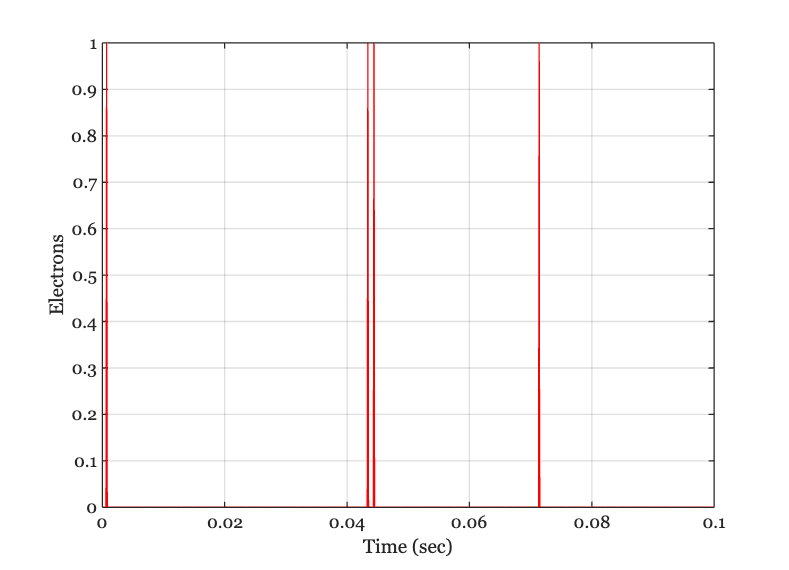

iePlot(T,electrons);
xlabel('Time (sec)'); ylabel('Electrons'); grid on

## Equivalent calculation

We do not have to do the calculation in two steps. The calculation is the same distribution if we combine the two probabilities. 

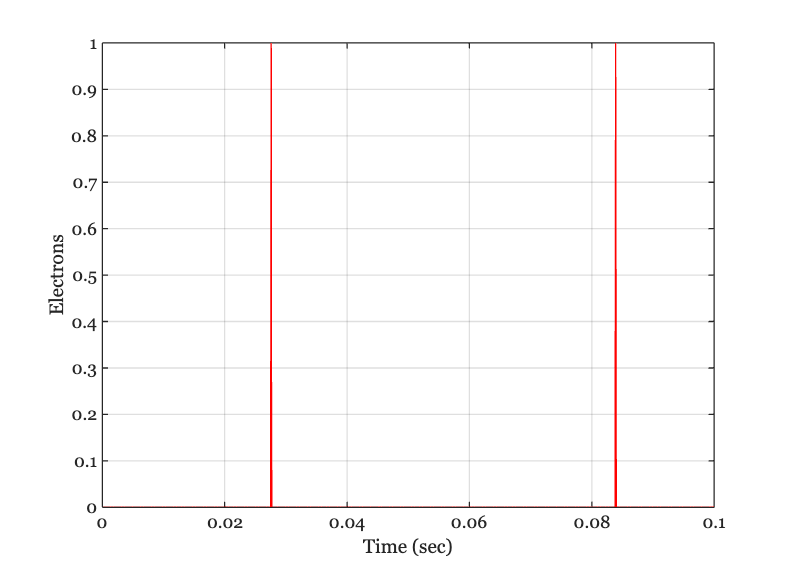

electrons2 = binornd(1,rho*epsilon,length(T),1);

iePlot(T,electrons2);
xlabel('Time (sec)');
ylabel('Electrons'); grid on

fprintf('There were %d electrons\n',sum(electrons2));

There were 2 electrons


## Counts

These should be close to the Poisson distribution, which is close to the Normal except when the Normal goes negative.

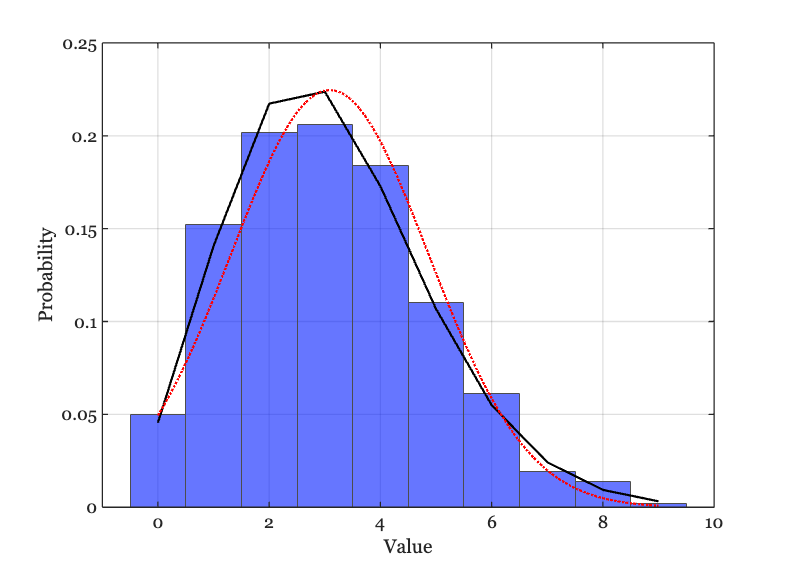

cnt = zeros(1,nSamples);
for ii=1:nSamples
    tmp = binornd(1,rho*epsilon,length(T),1);
    cnt(ii) = sum(tmp);
end

% Counts and standard deviation of the counts
mu = mean(cnt);
sigma = std(cnt);

% Create the histogram
ieFigure;
h = histogram(cnt, 'Normalization', 'probability');
h.EdgeColor = [0.3 0.3 0.3];
h.FaceColor = [0.0 0.1 1];

hold on; % Prevent the next plot from overwriting the histogram

% Calculate the Probability Mass Function (PMF) of the Poisson distribution
xmin = min(cnt);
xmax = max(cnt);
x = xmin:xmax;
lambda = mu;
f = (lambda.^x .* exp(-lambda)) ./ factorial(x);   
plot(x, f, 'k-', 'LineWidth', 2); % 'r-' for a red solid line

% Calculate the probability density function (PDF) of the Normal distribution
x = linspace(min(cnt), max(cnt), 100);
f = exp(-(x - mu).^2 / (2 * sigma^2)) / (sigma * sqrt(2 * pi));
plot(x, f, 'r:', 'LineWidth', 2); % 'r-' for a red solid line

% Add labels and title
xlabel('Value');
ylabel('Probability');

hold off; % Allow subsequent plots to overwrite this one
grid on;

The mean and variance are equal in the Poisson.  So these should be close.  The problem with the Normal is that it predicts some negative values.  The Poisson does not.  Everything is positive, so for small means they differ.

fprintf('Mean %.3f Variance %0.3f\n',mean(cnt),var(cnt));

Mean 3.089 Variance 3.154
